# Løsning på lortet

## Opgave 1

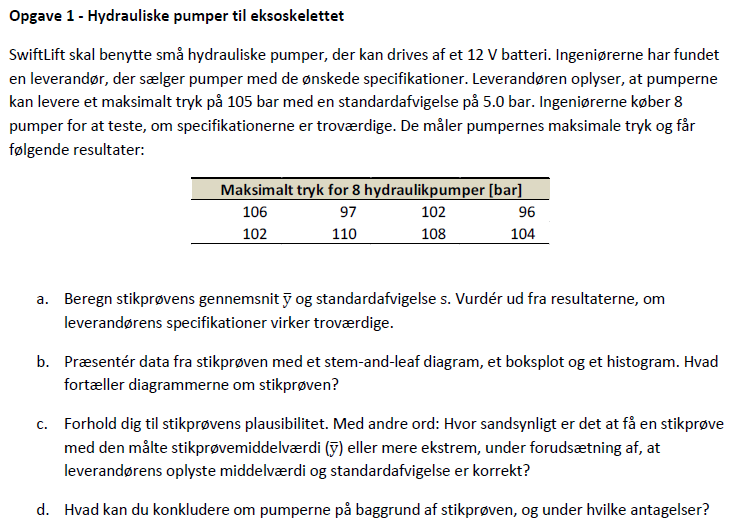

clc; clear all;

% Data indlæses
data = xlsread("Data_M4STI1_2018E (1).xlsx", 'A:A');

% Opgave a
D = sort(data)

D =     96
    97
   102
   102
   104
   106
   108
   110



n = length(D)       % Antal datapunkter

n = 8

mdl = mean(data)    % Stikprøvens middelværdi

mdl = 103.1250

stdafv = std(D)  % Populationsdata, derfor n-1

stdafv = 4.9407


afv = [mdl + stdafv; mdl - stdafv]

afv =   108.0657
   98.1843



max(D), min(D)

ans = 110

ans = 96


% Det ses at gennemsnittet +/- 1 standard afvigelse ligger indenfor rækkeviden min, max i datasættet

% Opgave b
D = data;
max(D)

ans = 110


stdafv = std(D)

stdafv = 4.9407


middel = mean(D)

middel = 103.1250

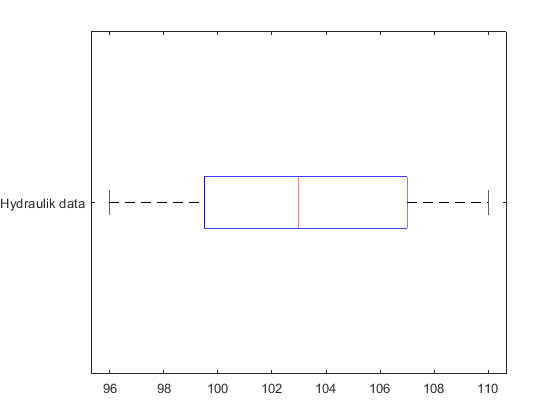


boxplot(D, 'Orientation','horizontal', 'Labels',{'Hydraulik data'})

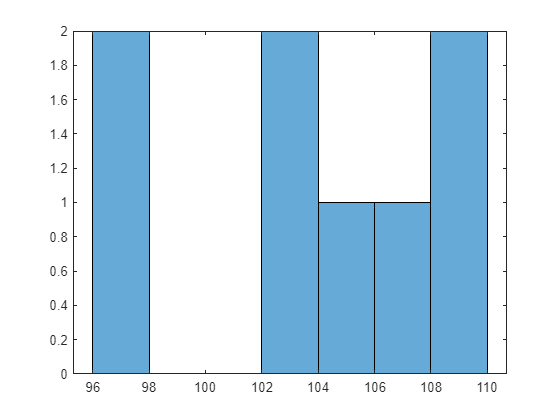

histogram(D, floor(min(D)):2:ceil(max(D)))


stemleafplot(D)

   9 | 6 7
  10 | 2 2 4 6 8
  11 | 0
key: 36|5 = 365
stem unit: 10
leaf unit: 1




prctile(D, [25,50,75])

ans =    99.5000  103.0000  107.0000


% Opgave c
% Observerede værdier
mu_obs = 105;
std_obs = 5;

% Udregnede stikprøve værdier
Ybar = mdl;
std_obs = stdafv;

% Den centrale grænseværdisætning antages
Z = (Ybar - mu_obs)/(std_obs/sqrt(n))

Z = -1.0734


% P(Z >= -1.0734)
ssh1 = normcdf(Z) % Ssh for at den er større end

ssh1 = 0.1415

ssh2 = 1 - normcdf(abs(Z))

ssh2 = 0.1415

ssh3 = ssh1 + ssh2

ssh3 = 0.2831


losningsforslag = 2*(1-normcdf(abs(Z)))

losningsforslag = 0.2831

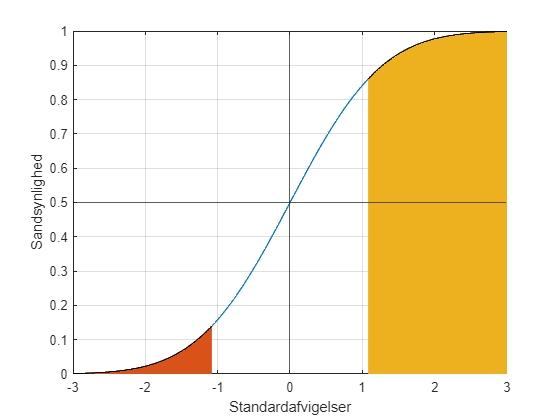

dist = makedist("Normal","mu",0,"sigma",1);
x = -3:0.01:3;

df = cdf(dist, x);
df1 = pdf(dist, x);

% Plot for forståelse
plot(x, df), xline(0), yline(0.5), grid(), xlabel("Standardafvigelser"), ylabel("Sandsynlighed")
hold on


x_less_Z = find(x < Z);
x_larger_Z = find(x > abs(Z));

% Komulativ fordelings plot
% mindre end Z
area(x(1, 1:length(x_less_Z)), df(1, 1:length(x_less_Z)));

% Større end Z
area(x(1, x_larger_Z(1):end), df(1, x_larger_Z(1):end));


hold off

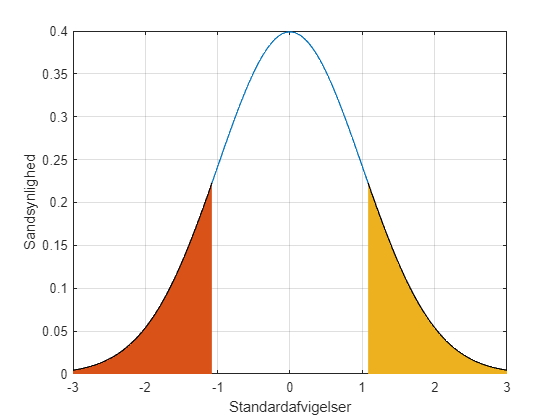


% Ssh plot
plot(x, df1), xlabel("Standardafvigelser"), ylabel("Sandsynlighed"), grid()
hold on
% mindre end Z
area(x(1, 1:length(x_less_Z)), df1(1, 1:length(x_less_Z)));

% Større end Z
area(x(1, x_larger_Z(1):end), df1(1, x_larger_Z(1):end));
hold off

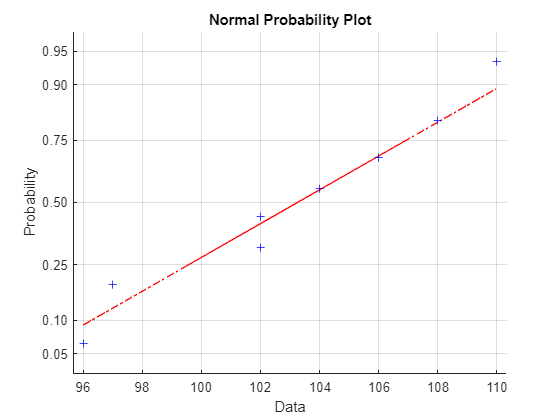


normplot(D)

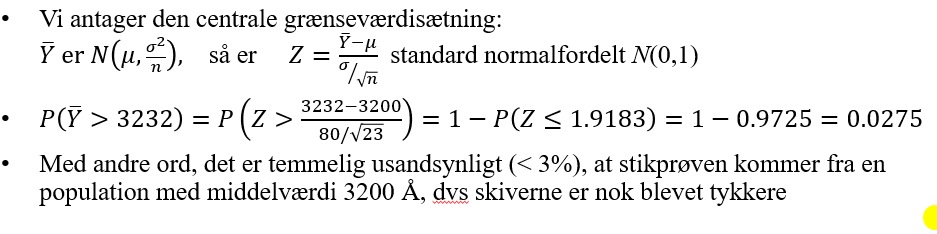

## Opgave 3

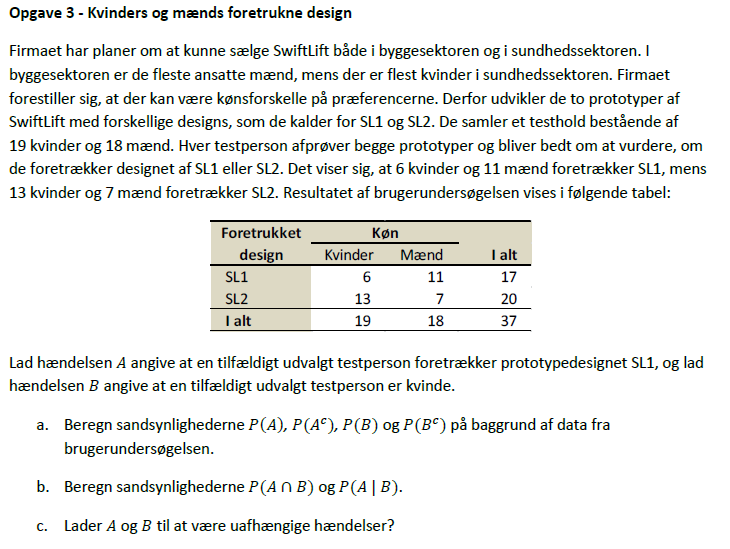

clc; clear all;

% SL1 data
sl1_k = 6

sl1_k = 6

sl1_m = 11 

sl1_m = 11

sl1_tot = sl1_k + sl1_m

sl1_tot = 17


% SL2 data
sl2_k = 13

sl2_k = 13

sl2_m = 7 

sl2_m = 7

sl2_tot = sl2_k + sl2_m

sl2_tot = 20


% Populations antal
n_tot = sl1_tot + sl2_tot

n_tot = 37


%---------------------------------------------%
%---------------- Udregninger ----------------%
%---------------------------------------------%

% Opgave a)
pA = sl1_tot/n_tot

pA = 0.4595

pAc = 1-pA

pAc = 0.5405

pB = (sl1_k + sl2_k)/n_tot

pB = 0.5135

pBc = 1 - pB

pBc = 0.4865


% Opgave b)
pA_og_B = sl1_k/n_tot

pA_og_B = 0.1622

pA_hvis_B = sl1_k/sl1_tot

pA_hvis_B = 0.3529


% Opgave c)
pA == pA_hvis_B

ans = logical
   0


% Ved tjek om de 2 hændelser er ens, ses det at resultatet er 0, altså
% false, så de er afhængige